# This Code Provide Analysis and Visualization For The Single Machine High Resolution AI Training Workload Profiles

## 1- Validation of HWiNFO and Python Monitroing Software Data

%%% Dataupload and Preperation 
addpath Validation_Test_Samples

% Read HWiNFO Data Records
HWTable=readtable("Validation_Test_Samples\Validation_HWinfo.CSV");

% remove the last two rows, which shows the min and max analysis as (NAN)
HWTable=HWTable(1:end-2,:); 

% Read The Python Monitoring Code
PyTable=readtable("Validation_Test_Samples\Validation_Reporting_Python_Monitoring.csv"); 

% get the time frame for each reference to ensure synchonization.
[~, m, s] = hms(HWTable.Time);
HW_time = m*60+s;
Py_time = 60*minute(PyTable.timestamp)+second(PyTable.timestamp);
time_ref=min(HW_time(1),Py_time(1));
HW_time=HW_time-time_ref;
Py_time=Py_time-time_ref;


### 1.1 TimeStep and Measurement Interval Validation 

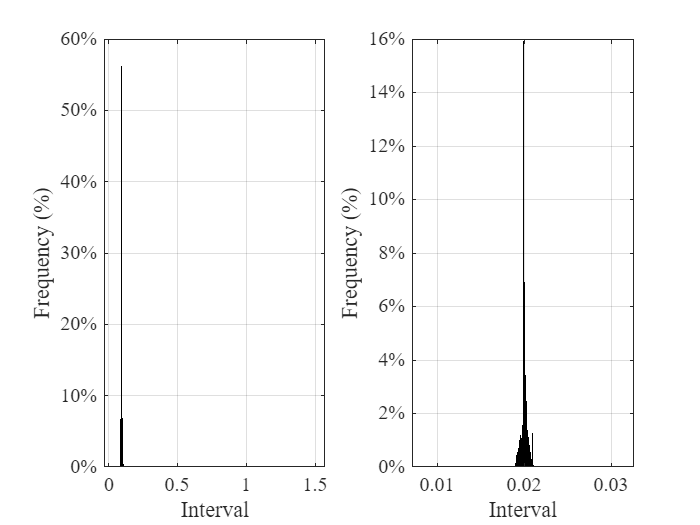

% HWiNFO Reporting Interval: 
Dt_HW=HW_time(2:end)-HW_time(1:end-1);

figure
subplot(1,2,1)
histogram(Dt_HW,Normalization="percentage")
ytickformat("percentage")
xlabel('Interval', 'FontName', 'Times New Roman', 'FontSize', 12)
ylabel('Frequency (%)', 'FontName', 'Times New Roman', 'FontSize', 12)
grid on
set(gca, 'FontName', 'Times New Roman', 'FontSize', 12)
% Pyhton Code Reporting Interval:
Dt_Py=Py_time(2:end)-Py_time(1:end-1);
subplot(1,2,2)
histogram(Dt_Py,Normalization="percentage")
ytickformat("percentage")
xlabel('Interval', 'FontName', 'Times New Roman', 'FontSize', 12)
ylabel('Frequency (%)', 'FontName', 'Times New Roman', 'FontSize', 12)
grid on
set(gca, 'FontName', 'Times New Roman', 'FontSize', 12)

### 1.2- Measurements Within Min/Max Range and CPU Power Validation Tests:

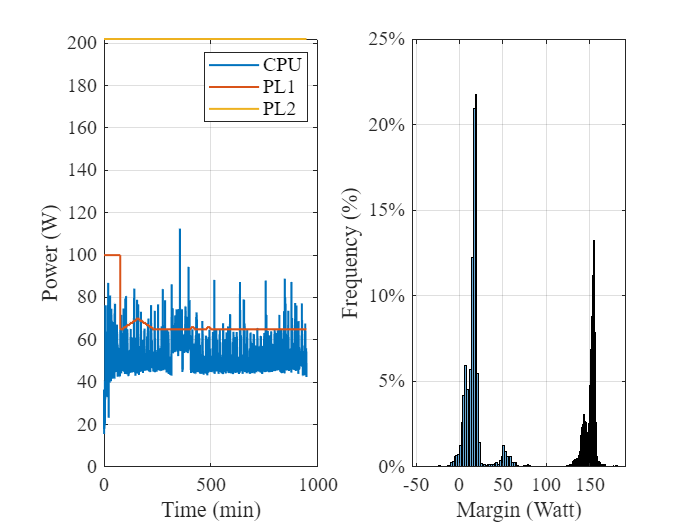

%%% CPU Power Limits
figure
subplot(1,2,1)
t_dis=max(HW_time);         
stairs(HW_time(HW_time<t_dis), HWTable.CPUPackagePower_W_(HW_time<t_dis), LineWidth=1.25, DisplayName='CPU');
hold on 
stairs(HW_time(HW_time<t_dis), HWTable.PL1PowerLimit_Dynamic__W_(HW_time<t_dis), LineWidth=1.25, DisplayName='PL1');
hold on 
stairs(HW_time(HW_time<t_dis), HWTable.PL2PowerLimit_Dynamic__W_(HW_time<t_dis), LineWidth=1.25, DisplayName='PL2');
xlabel('Time (min)', 'FontName', 'Times New Roman', 'FontSize', 12)
ylabel('Power (W)', 'FontName', 'Times New Roman', 'FontSize', 12)
grid on
set(gca, 'FontName', 'Times New Roman', 'FontSize', 12)
legend('FontName', 'Times New Roman', 'FontSize', 12)

% Margin From the PL1 and PL2 limits
subplot(1,2,2)
histogram((HWTable.PL1PowerLimit_Dynamic__W_-HWTable.CPUPackagePower_W_),Normalization="percentage")
hold on 
histogram((HWTable.PL2PowerLimit_Dynamic__W_-HWTable.CPUPackagePower_W_),Normalization="percentage")
ytickformat("percentage")
xlabel('Margin (Watt)', 'FontName', 'Times New Roman', 'FontSize', 12)
ylabel('Frequency (%)', 'FontName', 'Times New Roman', 'FontSize', 12)
grid on
set(gca, 'FontName', 'Times New Roman', 'FontSize', 12)



%%% GPU Analysis:
figure
subplot(1,2,1)
t_dis=60  

t_dis = 60

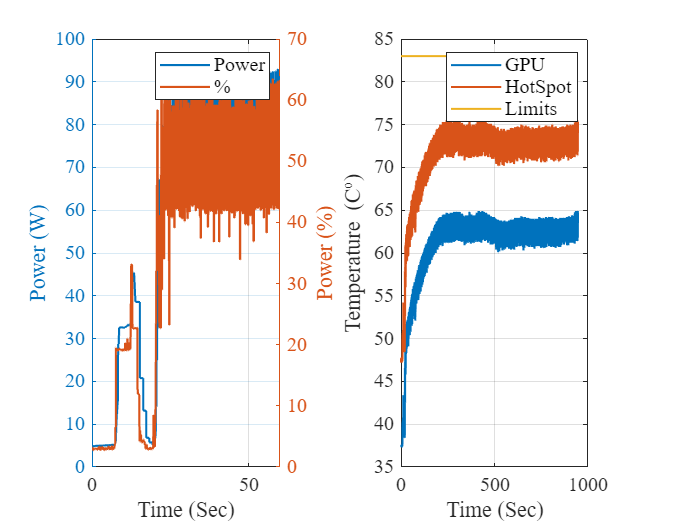

yyaxis left
stairs(HW_time(HW_time<t_dis), HWTable.GPUPower_W_(HW_time<t_dis), LineWidth=1.25, DisplayName='Power');
ylabel('Power (W)', 'FontName', 'Times New Roman', 'FontSize', 12)
hold on 
yyaxis right
stairs(HW_time(HW_time<t_dis), HWTable.TotalGPUPower__OfTDP____(HW_time<t_dis), LineWidth=1.25, DisplayName='%');
xlabel('Time (Sec)', 'FontName', 'Times New Roman', 'FontSize', 12)
ylabel('Power (%)', 'FontName', 'Times New Roman', 'FontSize', 12)
grid on
set(gca, 'FontName', 'Times New Roman', 'FontSize', 12)
legend('FontName', 'Times New Roman', 'FontSize', 12)

% Temp Limits
subplot(1,2,2)
t_dis=max(HW_time);         
stairs(HW_time(HW_time<t_dis), HWTable.GPUTemperature__C_(HW_time<t_dis), LineWidth=1.25, DisplayName='GPU');
hold on 
stairs(HW_time(HW_time<t_dis), HWTable.GPUHotSpotTemperature__C_(HW_time<t_dis), LineWidth=1.25, DisplayName='HotSpot');
hold on 
stairs(HW_time(HW_time<t_dis), HWTable.GPUThermalLimit__C_(HW_time<t_dis), LineWidth=1.25, DisplayName='Limits');
xlabel('Time (Sec)', 'FontName', 'Times New Roman', 'FontSize', 12)
ylabel('Temperature (C^o)', 'FontName', 'Times New Roman', 'FontSize', 12)
grid on
set(gca, 'FontName', 'Times New Roman', 'FontSize', 12)
legend('FontName', 'Times New Roman', 'FontSize', 12)

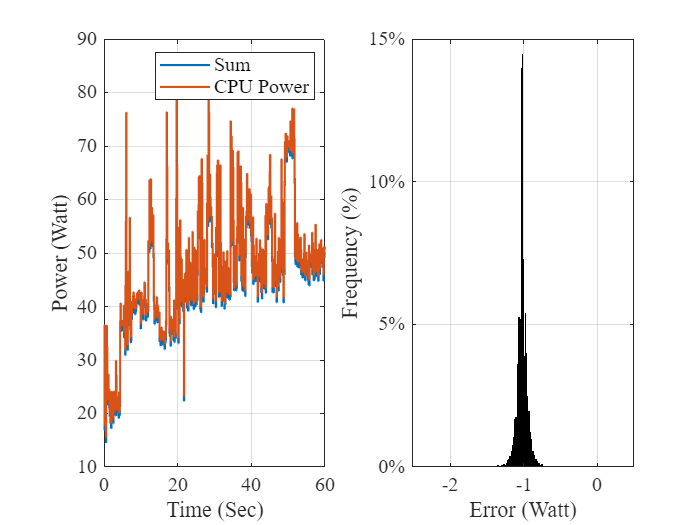




%%% Power Validation Analysis 
% CPU Package Power
total_CPU_Power=HWTable.IACoresPower_W_+HWTable.GTCoresPower_W_+HWTable.SystemAgentPower_W_+HWTable.Rest_of_ChipPower_W_;
figure
subplot(1,2,1)
t_dis=60;  
stairs(HW_time(HW_time<t_dis), total_CPU_Power(HW_time<t_dis), LineWidth=1.25, DisplayName='Sum');
hold on 
stairs(HW_time(HW_time<t_dis), HWTable.CPUPackagePower_W_(HW_time<t_dis), LineWidth=1.25, DisplayName='CPU Power');
xlabel('Time (Sec)', 'FontName', 'Times New Roman', 'FontSize', 12)
ylabel('Power (Watt)', 'FontName', 'Times New Roman', 'FontSize', 12)
grid on
set(gca, 'FontName', 'Times New Roman', 'FontSize', 12)
legend('FontName', 'Times New Roman', 'FontSize', 12)

% Error  
%total_GPU_Power=HWTable.GPUPCIe_12VInputPower_W_+HWTable.GPU8_pin_1InputPower_W_;
subplot(1,2,2)
histogram((total_CPU_Power-HWTable.CPUPackagePower_W_),Normalization="percentage")
ytickformat("percentage")
xlabel('Error (Watt)', 'FontName', 'Times New Roman', 'FontSize', 12)
ylabel('Frequency (%)', 'FontName', 'Times New Roman', 'FontSize', 12)
grid on
set(gca, 'FontName', 'Times New Roman', 'FontSize', 12)

### 1.3- Measurements Validation of HWiNFO and Python Monitoring Code 

#### GPU Power: 

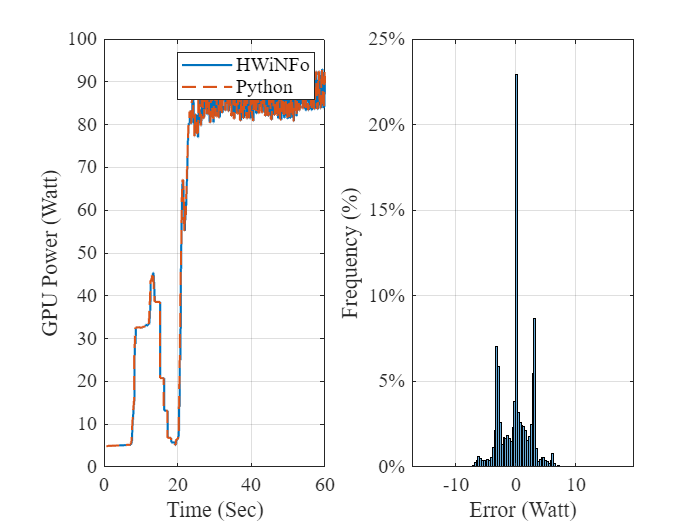

% Use Fixed-Interval Interpolation, HWiNfo measurements at the same time
% GPU Power: GPU Power Can be used, as both HWinfo and Python Monitoring
% have same driver reporting rate, and resolution, esnuring both are
% synchronized.
HWInt_GPU_PW=interp1(HW_time,HWTable.GPUPower_W_, Py_time, 'previous', 'extrap');
figure
subplot(1,2,1)
t_dis=60;         % Print the first 60-sec only 
stairs(Py_time(Py_time<t_dis), HWInt_GPU_PW(Py_time<t_dis), LineWidth=1.25, DisplayName='HWiNFo');
hold on 
stairs(Py_time(Py_time<t_dis), PyTable.gpu0_power_W(Py_time<t_dis), LineWidth=1.25, LineStyle="--", DisplayName='Python');
xlabel('Time (Sec)', 'FontName', 'Times New Roman', 'FontSize', 12)
ylabel('GPU Power (Watt)', 'FontName', 'Times New Roman', 'FontSize', 12)
grid on
set(gca, 'FontName', 'Times New Roman', 'FontSize', 12)
legend('FontName', 'Times New Roman', 'FontSize', 12)

subplot(1,2,2)
histogram(HWInt_GPU_PW-PyTable.gpu0_power_W,Normalization="percentage")
ytickformat("percentage")
xlabel('Error (Watt)', 'FontName', 'Times New Roman', 'FontSize', 12)
ylabel('Frequency (%)', 'FontName', 'Times New Roman', 'FontSize', 12)
grid on
set(gca, 'FontName', 'Times New Roman', 'FontSize', 12)

## 2- Physical and Technical DataSet Validation

### 2.1- CPU Paramaters Validation:

% Plot CPU Correlation Parameters:
% Power and Utilization
figure
subplot(1,3,1)
t_dis=5;              % Print the first 60-sec only 
yyaxis left 
stairs(HW_time(HW_time<t_dis), HWTable.CPUPackagePower_W_(HW_time<t_dis), LineWidth=1.25, DisplayName='Power');
ylabel('Power (Watt)', 'FontName', 'Times New Roman', 'FontSize', 12)
hold on 
yyaxis right
stairs(HW_time(HW_time<t_dis), HWTable.TotalCPUUtility___(HW_time<t_dis), LineWidth=1.25, DisplayName='Uti');
hold on 
stairs(HW_time(HW_time<t_dis), HWTable.TotalCPUUsage___(HW_time<t_dis), LineWidth=1.25, DisplayName='Usage');
xlabel('Time (Sec)', 'FontName', 'Times New Roman', 'FontSize', 12)
ylabel('Utilization (%)', 'FontName', 'Times New Roman', 'FontSize', 12)
grid on
set(gca,'FontName', 'Times New Roman', 'FontSize', 12)
legend('FontName', 'Times New Roman', 'FontSize', 12)

% Power and Temperature 
subplot(1,3,2)
yyaxis left 
stairs(HW_time(HW_time<t_dis), HWTable.CPUPackagePower_W_(HW_time<t_dis), LineWidth=1.25, DisplayName='Power');
ylabel('Power (Watt)', 'FontName', 'Times New Roman', 'FontSize', 12)
hold on 
yyaxis right
stairs(HW_time(HW_time<t_dis), HWTable.CoreTemperatures_avg___C_(HW_time<t_dis), LineWidth=1.25, DisplayName='Temp');
xlabel('Time (Sec)', 'FontName', 'Times New Roman', 'FontSize', 12)
ylabel('Temperatures (C^o)', 'FontName', 'Times New Roman', 'FontSize', 12)
grid on
set(gca,'FontName', 'Times New Roman', 'FontSize', 12)
legend('FontName', 'Times New Roman', 'FontSize', 12)

% Power and Current 
subplot(1,3,3)
yyaxis left 
stairs(HW_time(HW_time<t_dis), HWTable.VRVCCPower_SVIDPOUT__W_(HW_time<t_dis), LineWidth=1.25, DisplayName='Power');
ylabel('Power (Watt)', 'FontName', 'Times New Roman', 'FontSize', 12)
hold on 
yyaxis right
stairs(HW_time(HW_time<t_dis), HWTable.VRVCCCurrent_SVIDIOUT__A_(HW_time<t_dis), LineWidth=1.25, DisplayName='Temp');
xlabel('Time (Sec)', 'FontName', 'Times New Roman', 'FontSize', 12)
ylabel('Current (A)', 'FontName', 'Times New Roman', 'FontSize', 12)
grid on
set(gca,'FontName', 'Times New Roman', 'FontSize', 12)
legend('FontName', 'Times New Roman', 'FontSize', 12)


% Draw Correlation Assessment: 
figure
subplot(1,3,1)
% utility
p = polyfit(HWTable.CPUPackagePower_W_,HWTable.TotalCPUUtility___,1);    % Linear Poly Fit
f = polyval(p,HWTable.CPUPackagePower_W_);
Val_corr=corr(HWTable.CPUPackagePower_W_,HWTable.TotalCPUUtility___);

scatter(HWTable.CPUPackagePower_W_, HWTable.TotalCPUUtility___, 25, 'o', 'filled',DisplayName='Uti');
hold on 
plot(HWTable.CPUPackagePower_W_,f,LineStyle="--");
eqn = string("y = " + p(1)) + "x + " + string(p(2));
corr_val=string("R_{Uti}=" + Val_corr);
%text(min(HWTable.CPUPackagePower_W_),max(HWTable.TotalCPUUtility___),eqn,"HorizontalAlignment","left","VerticalAlignment","top")
text(min(HWTable.CPUPackagePower_W_),max(HWTable.TotalCPUUtility___),corr_val,"HorizontalAlignment","left","VerticalAlignment","middle")
xlabel('CPU Power (Watt)', 'FontName', 'Times New Roman', 'FontSize', 12)
ylabel('Uti/Usage (%)', 'FontName', 'Times New Roman', 'FontSize', 12)
grid on
set(gca,'FontName', 'Times New Roman', 'FontSize', 12)
legend('FontName', 'Times New Roman', 'FontSize', 12)

% Usage
p = polyfit(HWTable.CPUPackagePower_W_,HWTable.TotalCPUUsage___,1);    % Linear Poly Fit
f = polyval(p,HWTable.CPUPackagePower_W_);
Val_corr=corr(HWTable.CPUPackagePower_W_,HWTable.TotalCPUUsage___);
hold on
scatter(HWTable.CPUPackagePower_W_,HWTable.TotalCPUUsage___, 25, 'o', 'filled',DisplayName='Uti');
hold on 
plot(HWTable.CPUPackagePower_W_,f,LineStyle="--");
eqn = string("y = " + p(1)) + "x + " + string(p(2));
corr_val=string("R_{Usage}=" + Val_corr);
text(min(HWTable.CPUPackagePower_W_),max(HWTable.TotalCPUUtility___),corr_val,"HorizontalAlignment","left","VerticalAlignment","top")


subplot(1,3,2)
% Temp
p = polyfit(HWTable.CPUPackagePower_W_,HWTable.CoreTemperatures_avg___C_,1);    % Linear Poly Fit
f = polyval(p,HWTable.CPUPackagePower_W_);
Val_corr=corr(HWTable.CPUPackagePower_W_,HWTable.CoreTemperatures_avg___C_);

scatter(HWTable.CPUPackagePower_W_, HWTable.CoreTemperatures_avg___C_, 25, 'o', 'filled',DisplayName='Temp');
hold on 
plot(HWTable.CPUPackagePower_W_,f,LineStyle="--");
eqn = string("y = " + p(1)) + "x + " + string(p(2));
corr_val=string("R_{Temp}=" + Val_corr);
%text(min(HWTable.CPUPackagePower_W_),max(HWTable.TotalCPUUtility___),eqn,"HorizontalAlignment","left","VerticalAlignment","top")
text(min(HWTable.CPUPackagePower_W_),max(HWTable.CoreTemperatures_avg___C_),corr_val,"HorizontalAlignment","left","VerticalAlignment","top")
xlabel('CPU Power (Watt)', 'FontName', 'Times New Roman', 'FontSize', 12)
ylabel('Temperature (C^{o})', 'FontName', 'Times New Roman', 'FontSize', 12)
grid on
set(gca,'FontName', 'Times New Roman', 'FontSize', 12)
legend('FontName', 'Times New Roman', 'FontSize', 12)


subplot(1,3,3)
% Current
p = polyfit(HWTable.VRVCCPower_SVIDPOUT__W_,HWTable.VRVCCCurrent_SVIDIOUT__A_,1);    % Linear Poly Fit
f = polyval(p,HWTable.VRVCCPower_SVIDPOUT__W_);
Val_corr=corr(HWTable.VRVCCPower_SVIDPOUT__W_,HWTable.VRVCCCurrent_SVIDIOUT__A_);

scatter(HWTable.VRVCCPower_SVIDPOUT__W_, HWTable.VRVCCCurrent_SVIDIOUT__A_, 25, 'o', 'filled',DisplayName='Current');
hold on 
plot(HWTable.VRVCCPower_SVIDPOUT__W_,f,LineStyle="--");
eqn = string("y = " + p(1)) + "x + " + string(p(2));
corr_val=string("R_{Current}=" + Val_corr);
%text(min(HWTable.CPUPackagePower_W_),max(HWTable.TotalCPUUtility___),eqn,"HorizontalAlignment","left","VerticalAlignment","top")
text(min(HWTable.CPUPackagePower_W_),max(HWTable.VRVCCCurrent_SVIDIOUT__A_),corr_val,"HorizontalAlignment","left","VerticalAlignment","top")
xlabel('VRR Power (Watt)', 'FontName', 'Times New Roman', 'FontSize', 12)
ylabel('VRR Current (A)', 'FontName', 'Times New Roman', 'FontSize', 12)
grid on
set(gca,'FontName', 'Times New Roman', 'FontSize', 12)
legend('FontName', 'Times New Roman', 'FontSize', 12)


### 2.2- GPU Paramaters Validation:

% Plot GPU Correlation Parameters:
% Power, Core, and Memory
figure
subplot(1,2,1)
t_dis=30;                    % Print the first 60-sec only 
yyaxis left 
stairs(HW_time(HW_time<t_dis), HWTable.GPUPower_W_(HW_time<t_dis), LineWidth=1.25, DisplayName='Power');
ylabel('Power (Watt)', 'FontName', 'Times New Roman', 'FontSize', 12)
hold on 
yyaxis right
stairs(HW_time(HW_time<t_dis), HWTable.GPUCoreLoad___(HW_time<t_dis), LineWidth=1.25, DisplayName='Core');
hold on 
stairs(HW_time(HW_time<t_dis), HWTable.GPUMemoryControllerLoad___(HW_time<t_dis), LineWidth=1.25, DisplayName='Memory');
xlabel('Time (Sec)', 'FontName', 'Times New Roman', 'FontSize', 12)
ylabel('Load (%)', 'FontName', 'Times New Roman', 'FontSize', 12)
grid on
set(gca,'FontName', 'Times New Roman', 'FontSize', 12)
legend('FontName', 'Times New Roman', 'FontSize', 12)

% Power and Tempeature
subplot(1,2,2)
t_dis=30;                    % Print the first 60-sec only 
yyaxis left 
stairs(HW_time(HW_time<t_dis), HWTable.GPUPower_W_(HW_time<t_dis), LineWidth=1.25, DisplayName='Power');
ylabel('Power (Watt)', 'FontName', 'Times New Roman', 'FontSize', 12)
hold on 
yyaxis right
stairs(HW_time(HW_time<t_dis), HWTable.GPUTemperature__C_(HW_time<t_dis), LineWidth=1.25, DisplayName='GPU');
hold on 
stairs(HW_time(HW_time<t_dis), HWTable.GPUHotSpotTemperature__C_(HW_time<t_dis), LineWidth=1.25, DisplayName='HotSpot');
xlabel('Time (Sec)', 'FontName', 'Times New Roman', 'FontSize', 12)
ylabel('Temperature (C^o)', 'FontName', 'Times New Roman', 'FontSize', 12)
grid on
set(gca,'FontName', 'Times New Roman', 'FontSize', 12)
legend('FontName', 'Times New Roman', 'FontSize', 12)


% Draw Correlation Assessment: 
figure
subplot(1,2,1)
% Core
p = polyfit(HWTable.GPUPower_W_,HWTable.GPUCoreLoad___,1);    % Linear Poly Fit
f = polyval(p,HWTable.GPUPower_W_);
Val_corr=corr(HWTable.GPUPower_W_,HWTable.GPUCoreLoad___);

scatter(HWTable.GPUPower_W_, HWTable.GPUCoreLoad___, 25, 'o', 'filled',DisplayName='Core');
hold on 
plot(HWTable.GPUPower_W_,f,LineStyle="--");
eqn = string("y = " + p(1)) + "x + " + string(p(2));
corr_val=string("R_{Core}=" + Val_corr);
%text(min(HWTable.CPUPackagePower_W_),max(HWTable.TotalCPUUtility___),eqn,"HorizontalAlignment","left","VerticalAlignment","top")
text(min(HWTable.GPUPower_W_),max(HWTable.GPUCoreLoad___),corr_val,"HorizontalAlignment","left","VerticalAlignment","middle")
xlabel('GPU Power (Watt)', 'FontName', 'Times New Roman', 'FontSize', 12)
ylabel('Load (%)', 'FontName', 'Times New Roman', 'FontSize', 12)
grid on
set(gca,'FontName', 'Times New Roman', 'FontSize', 12)
legend('FontName', 'Times New Roman', 'FontSize', 12)

% Usage
p = polyfit(HWTable.GPUPower_W_,HWTable.GPUMemoryControllerLoad___,1);    % Linear Poly Fit
f = polyval(p,HWTable.GPUPower_W_);
Val_corr=corr(HWTable.GPUPower_W_,HWTable.GPUMemoryControllerLoad___);
hold on
scatter(HWTable.GPUPower_W_,HWTable.GPUMemoryControllerLoad___, 25, 'o', 'filled',DisplayName='Memory');
hold on 
plot(HWTable.GPUPower_W_,f,LineStyle="--");
eqn = string("y = " + p(1)) + "x + " + string(p(2));
corr_val=string("R_{Memory}=" + Val_corr);
text(min(HWTable.GPUPower_W_),max(HWTable.GPUMemoryControllerLoad___),corr_val,"HorizontalAlignment","left","VerticalAlignment","top")

% Temp
subplot(1,2,2)
% Core
p = polyfit(HWTable.GPUPower_W_,HWTable.GPUTemperature__C_,1);    % Linear Poly Fit
f = polyval(p,HWTable.GPUPower_W_);
Val_corr=corr(HWTable.GPUPower_W_,HWTable.GPUTemperature__C_);

scatter(HWTable.GPUPower_W_, HWTable.GPUTemperature__C_, 25, 'o', 'filled',DisplayName='GPU');
hold on 
plot(HWTable.GPUPower_W_,f,LineStyle="--");
eqn = string("y = " + p(1)) + "x + " + string(p(2));
corr_val=string("R_{GPU}=" + Val_corr);
%text(min(HWTable.CPUPackagePower_W_),max(HWTable.TotalCPUUtility___),eqn,"HorizontalAlignment","left","VerticalAlignment","top")
text(min(HWTable.GPUPower_W_),max(HWTable.GPUTemperature__C_),corr_val,"HorizontalAlignment","left","VerticalAlignment","middle")
xlabel('GPU Power (Watt)', 'FontName', 'Times New Roman', 'FontSize', 12)
ylabel('Temperature (C^o)', 'FontName', 'Times New Roman', 'FontSize', 12)
grid on
set(gca,'FontName', 'Times New Roman', 'FontSize', 12)
legend('FontName', 'Times New Roman', 'FontSize', 12)

% HotSpot
p = polyfit(HWTable.GPUPower_W_,HWTable.GPUHotSpotTemperature__C_,1);    % Linear Poly Fit
f = polyval(p,HWTable.GPUPower_W_);
Val_corr=corr(HWTable.GPUPower_W_,HWTable.GPUHotSpotTemperature__C_);
hold on
scatter(HWTable.GPUPower_W_,HWTable.GPUHotSpotTemperature__C_, 25, 'o', 'filled',DisplayName='HotSpot');
hold on 
plot(HWTable.GPUPower_W_,f,LineStyle="--");
eqn = string("y = " + p(1)) + "x + " + string(p(2));
corr_val=string("R_{HotSpot}=" + Val_corr);
text(min(HWTable.GPUPower_W_),max(HWTable.GPUHotSpotTemperature__C_),corr_val,"HorizontalAlignment","left","VerticalAlignment","top")


### 2.3 AI Model and Hyper Paramaters Validation